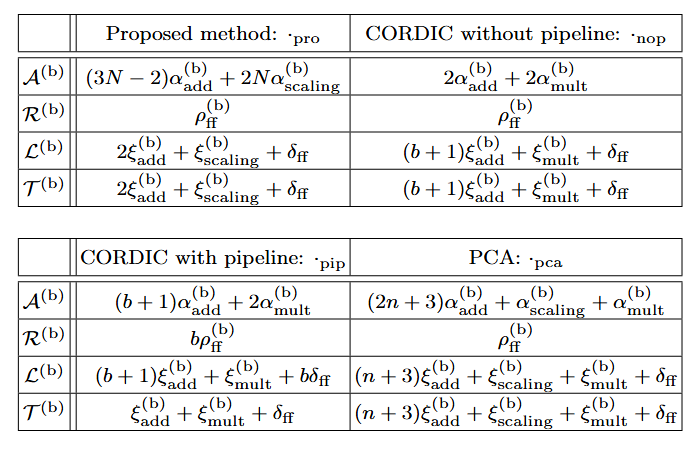

% clear

mykey = [ "pron2", "pron3", "pron4", "nop", "pip", "pca10", "pca50"].';
cval = ["#0072bd", "#50a2d8", "#95c0dd", "#ffbc00", "#cfb200", "#d95319", "#d97d55"].';
tbl = table(mykey,cval)

tbl = 7×2 table
     mykey       cval   
    _______    _________

    "pron2"    "#0072bd"
    "pron3"    "#50a2d8"
    "pron4"    "#95c0dd"
    "nop"      "#ffbc00"
    "pip"      "#cfb200"
    "pca10"    "#d95319"
    "pca50"    "#d97d55"


% Device characteristics
syms alpha_add xi_add
syms delta_ff

% Meta variables
syms beta gamma

% Assumptions
alpha_scaling = beta*alpha_add

$$alpha\_scaling = \alpha_{\mathrm{add}}\,\beta$$

alpha_mult = gamma*alpha_add

$$alpha\_mult = \alpha_{\mathrm{add}}\,\gamma$$

xi_scaling = beta*xi_add

$$xi\_scaling = \beta \,\xi_{\mathrm{add}}$$

xi_mult = gamma*xi_add

$$xi\_mult = \gamma \,\xi_{\mathrm{add}}$$


% Circuit configuration
syms b

## Circuit area

a = cell(height(tbl),1);
% Proposals
a_prop = @(N) (3*N-2)*alpha_add + 2*N*alpha_scaling;
a{1} = @(beta,gamma) a_prop(2);
a{2} = @(beta,gamma) a_prop(3);
a{3} = @(beta,gamma) a_prop(4);
% CORDIC
a{4} = @(beta,gamma) 2*alpha_add + 2*alpha_mult;
a{5} = @(beta,gamma) (b+1)*alpha_add+2*alpha_mult;
% PCA
%a_pca = @(n) (2*n+3)*alpha_add+alpha_scaling+alpha_mult;
a_pca = @(n) (n+4)*alpha_add+alpha_scaling+alpha_mult;
a{6} = @(beta,gamma) a_pca(10);
a{7} = @(beta,gamma) a_pca(50);

% Table
tbl.Ab = a;
for idx = 1:height(tbl)
    disp("Ab_"+tbl.mykey(idx)+" = ")
    disp(a{idx}(1))
end

Ab_pron2 = 


$$4\,\alpha_{\mathrm{add}}+4\,\alpha_{\mathrm{add}}\,\beta$$

Ab_pron3 = 


$$7\,\alpha_{\mathrm{add}}+6\,\alpha_{\mathrm{add}}\,\beta$$

Ab_pron4 = 


$$10\,\alpha_{\mathrm{add}}+8\,\alpha_{\mathrm{add}}\,\beta$$

Ab_nop = 


$$2\,\alpha_{\mathrm{add}}+2\,\alpha_{\mathrm{add}}\,\gamma$$

Ab_pip = 


$$2\,\alpha_{\mathrm{add}}\,\gamma +\alpha_{\mathrm{add}}\,\left(b+1\right)$$

Ab_pca10 = 


$$14\,\alpha_{\mathrm{add}}+\alpha_{\mathrm{add}}\,\beta +\alpha_{\mathrm{add}}\,\gamma$$

Ab_pca50 = 


$$54\,\alpha_{\mathrm{add}}+\alpha_{\mathrm{add}}\,\beta +\alpha_{\mathrm{add}}\,\gamma$$


for idx = 1:height(tbl)
    disp("Ab_"+tbl.mykey(idx)+" = ")
    disp(subs(a{idx}(1),alpha_add,1))
end

Ab_pron2 = 


$$4\,\beta +4$$

Ab_pron3 = 


$$6\,\beta +7$$

Ab_pron4 = 


$$8\,\beta +10$$

Ab_nop = 


$$2\,\gamma +2$$

Ab_pip = 


$$b+2\,\gamma +1$$

Ab_pca10 = 


$$\beta +\gamma +14$$

Ab_pca50 = 


$$\beta +\gamma +54$$

## Latency

l = cell(height(tbl),1);
% Proposals
l_prop = @(N) 2*xi_add + xi_scaling + delta_ff;
l{1} = @(beta,gamma) l_prop(2);
l{2} = @(beta,gamma) l_prop(3);
l{3} = @(beta,gamma) l_prop(4);
% CORDIC
l{4} = @(beta,gamma) (b+1)*xi_add+xi_mult+delta_ff;
l{5} = @(beta,gamma) (b+1)*xi_add+xi_mult+b*delta_ff;
% PCA
l_pca = @(n) (n+3)*xi_add+xi_scaling+xi_mult+delta_ff;
l{6} = @(beta,gamma) l_pca(10);
l{7} = @(beta,gamma) l_pca(50);

% Table
tbl.Lb = l;
for idx = 1:height(tbl)
    disp("Lb_"+tbl.mykey(idx)+" = ")
    disp(l{idx}(1))
end

Lb_pron2 = 


$$\delta_{\mathrm{ff}}+2\,\xi_{\mathrm{add}}+\beta \,\xi_{\mathrm{add}}$$

Lb_pron3 = 


$$\delta_{\mathrm{ff}}+2\,\xi_{\mathrm{add}}+\beta \,\xi_{\mathrm{add}}$$

Lb_pron4 = 


$$\delta_{\mathrm{ff}}+2\,\xi_{\mathrm{add}}+\beta \,\xi_{\mathrm{add}}$$

Lb_nop = 


$$\delta_{\mathrm{ff}}+\gamma \,\xi_{\mathrm{add}}+\xi_{\mathrm{add}}\,\left(b+1\right)$$

Lb_pip = 


$$b\,\delta_{\mathrm{ff}}+\gamma \,\xi_{\mathrm{add}}+\xi_{\mathrm{add}}\,\left(b+1\right)$$

Lb_pca10 = 


$$\delta_{\mathrm{ff}}+13\,\xi_{\mathrm{add}}+\beta \,\xi_{\mathrm{add}}+\gamma \,\xi_{\mathrm{add}}$$

Lb_pca50 = 


$$\delta_{\mathrm{ff}}+53\,\xi_{\mathrm{add}}+\beta \,\xi_{\mathrm{add}}+\gamma \,\xi_{\mathrm{add}}$$

for idx = 1:height(tbl)
    disp("Lb_"+tbl.mykey(idx)+" = ")
    disp(subs(l{idx}(1),xi_add,1))
end

Lb_pron2 = 


$$\beta +\delta_{\mathrm{ff}}+2$$

Lb_pron3 = 


$$\beta +\delta_{\mathrm{ff}}+2$$

Lb_pron4 = 


$$\beta +\delta_{\mathrm{ff}}+2$$

Lb_nop = 


$$b+\delta_{\mathrm{ff}}+\gamma +1$$

Lb_pip = 


$$b+\gamma +b\,\delta_{\mathrm{ff}}+1$$

Lb_pca10 = 


$$\beta +\delta_{\mathrm{ff}}+\gamma +13$$

Lb_pca50 = 


$$\beta +\delta_{\mathrm{ff}}+\gamma +53$$

## Throughput

t = cell(height(tbl),1);
% Proposals
t_prop = @(N) 2*xi_add+xi_scaling+delta_ff;
t{1} = @(beta,gamma) t_prop(2);
t{2} = @(beta,gamma) t_prop(3);
t{3} = @(beta,gamma) t_prop(4);
% CORDIC
t{4} = @(beta,gamma) (b+1)*xi_add+xi_mult+delta_ff;
t{5} = @(beta,gamma) xi_add+xi_mult+delta_ff;
% PCA
t_pca = @(n) (n+3)*xi_add+xi_scaling+xi_mult+delta_ff;
t{6} = @(beta,gamma) t_pca(10);
t{7} = @(beta,gamma) t_pca(50);

% Table
tbl.Tb = t;
for idx = 1:height(tbl)
    disp("Tb_"+tbl.mykey(idx)+" = ")
    disp(t{idx}(1))
end

Tb_pron2 = 


$$\delta_{\mathrm{ff}}+2\,\xi_{\mathrm{add}}+\beta \,\xi_{\mathrm{add}}$$

Tb_pron3 = 


$$\delta_{\mathrm{ff}}+2\,\xi_{\mathrm{add}}+\beta \,\xi_{\mathrm{add}}$$

Tb_pron4 = 


$$\delta_{\mathrm{ff}}+2\,\xi_{\mathrm{add}}+\beta \,\xi_{\mathrm{add}}$$

Tb_nop = 


$$\delta_{\mathrm{ff}}+\gamma \,\xi_{\mathrm{add}}+\xi_{\mathrm{add}}\,\left(b+1\right)$$

Tb_pip = 


$$\delta_{\mathrm{ff}}+\xi_{\mathrm{add}}+\gamma \,\xi_{\mathrm{add}}$$

Tb_pca10 = 


$$\delta_{\mathrm{ff}}+13\,\xi_{\mathrm{add}}+\beta \,\xi_{\mathrm{add}}+\gamma \,\xi_{\mathrm{add}}$$

Tb_pca50 = 


$$\delta_{\mathrm{ff}}+53\,\xi_{\mathrm{add}}+\beta \,\xi_{\mathrm{add}}+\gamma \,\xi_{\mathrm{add}}$$


for idx = 1:height(tbl)
    disp("Tb_"+tbl.mykey(idx)+" = ")
    disp(subs(t{idx}(1),xi_add,1))
end

Tb_pron2 = 


$$\beta +\delta_{\mathrm{ff}}+2$$

Tb_pron3 = 


$$\beta +\delta_{\mathrm{ff}}+2$$

Tb_pron4 = 


$$\beta +\delta_{\mathrm{ff}}+2$$

Tb_nop = 


$$b+\delta_{\mathrm{ff}}+\gamma +1$$

Tb_pip = 


$$\delta_{\mathrm{ff}}+\gamma +1$$

Tb_pca10 = 


$$\beta +\delta_{\mathrm{ff}}+\gamma +13$$

Tb_pca50 = 


$$\beta +\delta_{\mathrm{ff}}+\gamma +53$$

## Graph Drawing

Assumption

assume(beta>1)
disp(assumptions(beta))

$$1<\beta$$

assume(gamma>beta)
disp(assumptions(gamma))

$$\beta <\gamma$$


assume(alpha_add == 1)
disp(assumptions(alpha_add))

$$\alpha_{\mathrm{add}}=1$$

assume(xi_add == 1)
disp(assumptions(xi_add))

$$\xi_{\mathrm{add}}=1$$

assume(delta_ff == 0)
disp(assumptions(delta_ff))

$$\delta_{\mathrm{ff}}=0$$


assume(b == 16)
disp(assumptions(b))

$$b=16$$

c = tbl.cval;
k = tbl.mykey;

betamax = 20;
gammamax = 20;
[betat,gammat] = meshgrid(0:0.2:betamax,0:0.2:gammamax);



### Circuit area / Latency / Throughput

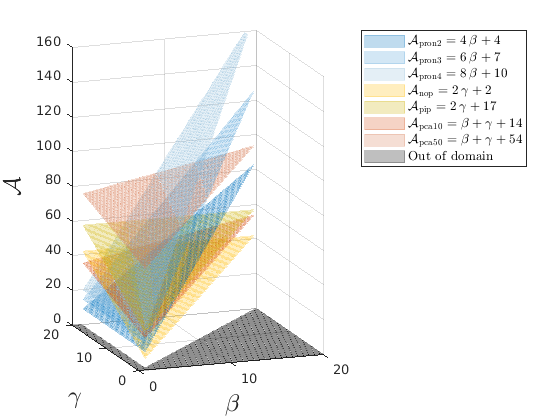

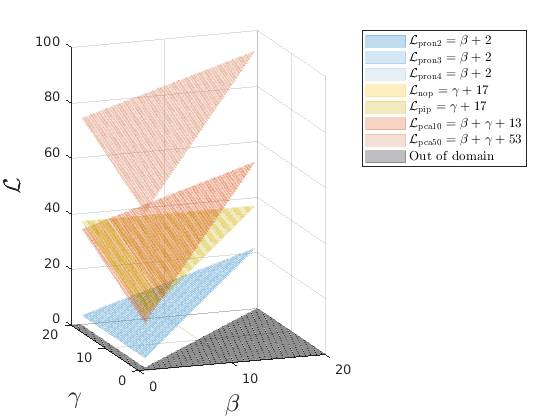

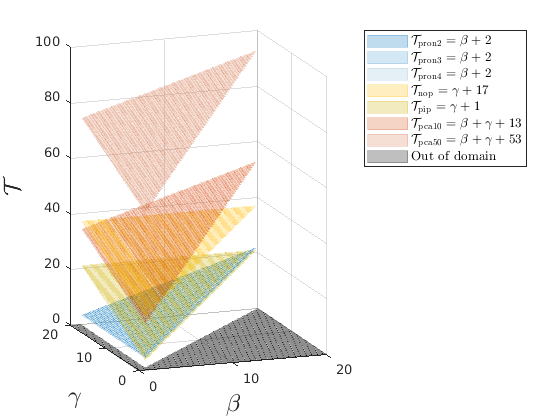

fs = {tbl.Ab, tbl.Lb, tbl.Tb};
zs = ["A", "L", "T"];
mx = [ 160, 100, 100 ];
for ieval = 1:length(fs)
    fig = figure();
    a = fs{ieval};
    z = zs(ieval);
    for idx = 1:height(tbl)
        %
        f = simplify(a{idx}(1));
        Z = feval(matlabFunction(f,'Vars',[beta gamma]),betat,gammat);
        Z(any(cat(3,betat>=gammat,betat <= 1,gammat <= 1),3)) = nan;
        h = surf(betat,gammat,Z);
        %
        h.FaceAlpha = 0.25;
        h.FaceColor = c{idx};
        h.EdgeColor = c{idx};
        h.EdgeAlpha = 0.25;
        h.DisplayName = "$\mathcal{"+z+"}_{\mathrm{"+k{idx}+"}} = "+latex(f)+"$";
        hold on
    end
    %
    C = zeros(size(betat));
    C(all(cat(3,betat<gammat,betat >1,gammat > 1),3)) = nan;
    hc = surf(betat,gammat,C);
    hc.EdgeColor = "k";
    hc.FaceColor = "k";
    hc.EdgeAlpha = 0.25;
    hc.FaceAlpha = 0.25;
    hc.DisplayName = "Out of domain";
    hold off
    %
    axis([0 betamax 0 gammamax 0 mx(ieval)])
    xlabel('$\beta$','Interpreter','latex','FontSize',18)
    ylabel('$\gamma$','Interpreter','latex','FontSize',18)
    zlabel("$\mathcal{"+z+"}$",'Interpreter','latex','FontSize',18)
    view(-20,10)
    legend('show', 'Interpreter', 'latex', 'FontSize', 10);
    %
    exportgraphics(fig,"abe_abseval"+ieval+".png")
end